# Chapter 2

*Original author: Allen Downey (2017)*

*Author: Zachary del Rosario (2020)*

% Set the random state
rng(101)

% NOTE: If this cell is successful, it produces no output

## Modeling a Bikeshare System

We'll start with a *table* object that represents the number of bikes at each station.

tab_bikeshare = fcn_make_table("olin", 10, "wellesley", 2);

When you display a table object, it lists its context:

tab_bikeshare

tab_bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     10         2    


We can access the individual *columns* of the table using dot notation.

tab_bikeshare.olin

ans = 10

tab_bikeshare.wellesley

ans = 2

**Exercise:** What happens if you spell the name of a state variable wrong?  Edit the previous cell, change the spelling of `wellesley` to `wesley`, and run the cell again.

% Solution
% tab_bikeshare.wesley

The error indicates that this table doesn't have the variable we're looking for. We can add a new variable using the same dot notation:

tab_bikeshare.mass_bay = 30

tab_bikeshare = 1×3 table
    olin    wellesley    mass_bay
    ____    _________    ________

     10         2           30   


**Exercise:** Add a third attribute called `babson` with initial value 0, and display the state of `bikeshare` again.

% Solution
tab_bikeshare.babson = 0;
tab_bikeshare

tab_bikeshare = 1×4 table
    olin    wellesley    mass_bay    babson
    ____    _________    ________    ______

     10         2           30         0   


## Updating

We can use assignment `=` to increase or decrease a property:

tab_bikeshare.olin = tab_bikeshare.olin - 1

tab_bikeshare = 1×4 table
    olin    wellesley    mass_bay    babson
    ____    _________    ________    ______

     9          2           30         0   


Of course, if we subtract a bike from `olin`, we should add it to `wellesley`.

tab_bikeshare.wellesley = tab_bikeshare.wellesley + 1

tab_bikeshare = 1×4 table
    olin    wellesley    mass_bay    babson
    ____    _________    ________    ______

     9          3           30         0   


## Functions

We can take the code we've written so far and encapsulate it in a function. In order to do this in Matlab, we have to create a new file with the same name; this notebook comes with many other files, including `fcn_olin2wellesley.m`. The contents of that file are repeated here for convenience, but know that *the function itself is defined in that external file.*

% NOTE: Leave this commented! This function is defined in the external file
% `fcn_olin2wellesley.m`
% function tab_state = fcn_olin2wellesley(tab_state)
% 
% tab_state.olin = tab_state.olin - 1;
% tab_state.wellesley = tab_state.wellesley + 1;
% 
% end

**Troubleshooting Note:** When trying to run Matlab functions, you might get an error message to the effect of `Unrecognized function or variable`. To see an example, uncomment and run the following code:

% TODO: Uncomment and try running this function
% fcn_not_a_real_function()

This often happens when Matlab is looking in the wrong place.

**The Fix:** To fix this kind of issue, Right click on the *tab* for your notebook---e.g. this notebook is `ch2_notebook.mlx`---and click **Change Current Folder to...** in order to tell Matlab to operate in the correct place. Try again: If your target function is in the same folder, then you should be able to run the code below.

*Aside*: The relevant concept here is the [working directory](https://en.wikipedia.org/wiki/Working_directory).

When you define a function, it doesn't run the statements inside the  function, yet. When you call the function, it runs the statements inside.

tab_bikeshare = fcn_olin2wellesley(tab_bikeshare)

tab_bikeshare = 1×4 table
    olin    wellesley    mass_bay    babson
    ____    _________    ________    ______

     8          4           30         0   


One common error is to omit the parentheses, which has the effect of looking up the function, but not calling it.

% NOTE: Uncomment and run the line below
% fcn_olin2wellesley

The output indicates that `fcn_olin2wellesley` is expecting more input arguments than what we gave (zero arguments).

**Exercise:** Create a new file `fcn_wellesley2olin.m` and a function called `fcn_wellesley2olin` that moves a bike from Wellesley to Olin.  Call the new function and display `bikeshare`  to confirm that it works.

% SOLUTION: Function definition
% function tab_state = fcn_wellesley2olin(tab_state)
% 
% tab_state.olin = tab_state.olin + 1;
% tab_state.wellesley = tab_state.wellesley - 1;
% 
% end

% SOLUTION: Calling the function
tab_bikeshare = fcn_wellesley2olin(tab_bikeshare)

tab_bikeshare = 1×4 table
    olin    wellesley    mass_bay    babson
    ____    _________    ________    ______

     9          3           30         0   


## Conditionals

The function coin returns 0 or 1 with a user-supplied probability. You can use the syntax `help function` to look up the documentation for a function.

help coin

  coin Return 1 or 0 with a given probability
 
  Usage
    res = coin(p)
 
  Arguments
    p = probability of returning the value 1; 
        `p` between 0 and 1, inclusive
 
  Returns
    res = 0 or 1



In the following example, the probability is 0.7 or 70%.  If you run this cell several times, you should get `True` about 70% of the time and `False` about 30%.

coin(0.7)

ans = 1

In the following example, we use coin as part of an if statement.  If the result from coin is 1, we print `heads`; otherwise we do nothing.

if coin(0.5) == 1
    disp("heads");
end

With an else clause, we can print heads or tails depending on whether coin returns 1 or 0.

if coin(0.5) == 1
    disp("heads");
else
    disp("tails");
end

heads


Note that since Matlab interprets the value `1` as "True", we can omit the `== 1` from the conditional.

if coin(0.5)
    disp("heads");
else
    disp("tails");
end

heads


**Mini-exercise:** Try executing the code `1 == 1` and `1 == 0`. What does Matlab return in those two cases?

% Solution
1 == 1

ans = logical
   1


1 == 0

ans = logical
   0


## Step

Now let's get back to the bikeshare state.  Again let's start with a new state.

tab_bikeshare = fcn_make_table("olin", 10, "wellesley", 2)

tab_bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     10         2    


Suppose that in any given minute, there is a 50% chance that a  student picks up a bike at Olin and rides to Wellesley.  We can simulate that like this.

if coin(0.5)
    tab_bikeshare = fcn_olin2wellesley(tab_bikeshare);
    disp("Moving a bike from Olin to Wellesley");
end
tab_bikeshare

tab_bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     10         2    


And maybe at the same time, there is also a 40% chance that a student at Wellesley rides to Olin.

if coin(0.4)
    tab_bikeshare = fcn_wellesley2olin(tab_bikeshare);
    disp("Moving a bike from Wellesley to Olin");
end
tab_bikeshare

tab_bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     10         2    


We can wrap that code in a function called bikeshare_step that  simulates one time step.  In any given minute, a student might ride from Olin to Wellesley, from Wellesley to Olin, or both, or neither,  depending on the results of coin.

% EXAMPLE: This is how we could package the steps above in a function
% function tab_state = fcn_step(tab_state)
% 
% if coin(0.5)
%     tab_state = fcn_olin2wellesley(tab_state);
%     disp("Moving a bike from Olin to Wellesley");
% end
% 
% if coin(0.4)
%     tab_state = fcn_wellesley2olin(tab_state);
%     disp("Moving a bike from Wellesley to Olin");
% end
% 
% end

## Parameters

However, we probably don't want to write fcn_step *quite* like that; it fixes the probabilities to particular values. To change them, we would have to go edit the source code. Instead, we can pass those as *parameters* to the function:

% NOTE: This function is defined in fcn_step.m`
% function tab_state = fcn_step(tab_state, p_o2w, p_w2o)
% % step Advance an Olin-Wellesley bikeshare system one timestep
% % 
% % Usage
% %   fcn_step(tab_state, p_o2w, p_w2o)
% %
% % Arguments
% %   tab_state = bikeshare state; must have variables `olin` and `wellesley`
% %   p_o2w = probability of a cyclist going Olin to Wellesley
% %   p_w2o = probability of a cyclist going Wellesley to Olin
% %
% % Examples
% %   tab_bikeshare = fcn_make_table("olin", 10, "wellesley", 3)
% %   tab_bikeshare = fcn_step(tab_bikeshare)
% 
% if coin(p_o2w)
%     tab_state = fcn_olin2wellesley(tab_state);
% end
% 
% if coin(p_w2o)
%     tab_state = fcn_wellesley2olin(tab_state);
% end
% 
% end

Now we can call it like this:

tab_bikeshare = fcn_step(tab_bikeshare, 0.5, 0.4);

**Exercise:** Open the file `step.m`; at the beginning of `step`, add a print statement that displays the values of `p1` and `p2`.  Call it again with values `0.3`, and `0.2`, and confirm that the values of the parameters are what you expect.

## For Loop

And let's start again with a new table.

tab_bikeshare = fcn_make_table("olin", 10, "wellesley", 2)

tab_bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     10         2    


We can use a `for` loop to move 4 bikes from Olin to Wellesley.

for i = 1 : 4
    tab_bikeshare = fcn_olin2wellesley(tab_bikeshare);
end
tab_bikeshare

tab_bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     6          6    


Or we can simulate 4 random time steps.

for i = 1 : 4
    tab_bikeshare = fcn_step(tab_bikeshare, 0.3, 0.2);
end
tab_bikeshare

tab_bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     6          6    


If each step corresponds to a minute, we can simulate an entire hour like this.

for i = 1 : 60
    tab_bikeshare = fcn_step(tab_bikeshare, 0.3, 0.2);
end
tab_bikeshare

tab_bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     -3        15    


After 60 minutes, you might see that the number of bike at Olin is negative.  We'll fix that problem in the next notebook.

## Tables

I mentioned this briefly before, but we're using a *table *to represent the state of our system:

tab_bikeshare

tab_bikeshare = 1×2 table
    olin    wellesley
    ____    _________

     -3        15    


A table is a particular kind of (Matlab) data structure. The tables we've made so far only have *one row*, but we can store multiple rows in a single table. This is very useful for creating a *record* of simulation results. We can do this by *concatenating *tables, which is just a fancy word that means combining two tables.

The bracket syntax tab_new = `[tab1; tab2]` returns a new table where the two are joined "vertically" (by rows). To illustrate:

tab1 = fcn_make_table("row", 1, "foo", 0);
tab2 = fcn_make_table("row", 2, "foo", 0);
tab_new = [tab1; tab2]

tab_new = 2×2 table
    row    foo
    ___    ___

     1      0 
     2      0 


Like with the `tab_state.olin = tab_state.olin + 1` code we wrote before, we can use similar syntax to *update *an existing table:

**Exercise: **Use bracket notation `[t1; t2] to update tab_new `with a third row.

% NOTE: Add this third table to tab_new
tab3 = fcn_make_table("row", 3, "foo", 0);
% Solution
tab_new = [tab_new; tab3]

tab_new = 3×2 table
    row    foo
    ___    ___

     1      0 
     2      0 
     3      0 


We can use this concatenation idea to *store records* as we carry out our simulation.

% Create an initial state
tab_bikeshare = fcn_make_table("olin", 10, "wellesley", 2);
% Create an empty table to record results
tab_record = fcn_make_table();

for i = 1 : 10
    % Advance the simulation
    tab_bikeshare = fcn_step(tab_bikeshare, 0.3, 0.2);
    % Record the results
    tab_record = [tab_record; tab_bikeshare];
end

tab_record

tab_record = 10×2 table
    olin    wellesley
    ____    _________

     11         1    
     12         0    
     13        -1    
     13        -1    
     13        -1    
     13        -1    
     13        -1    
     12         0    
     11         1    
     10         2    


Great! Now we have a history of our simulation. However, it's difficult to make sense of our data by staring at raw counts. Instead, let's *plot* the data.

## Plotting

The following is bare-bones code to plot our bikeshare data. The `plot()` function simply draws a line plot of the provided data.

*Note*: We'll see why we need the preamble stuff in a bit.

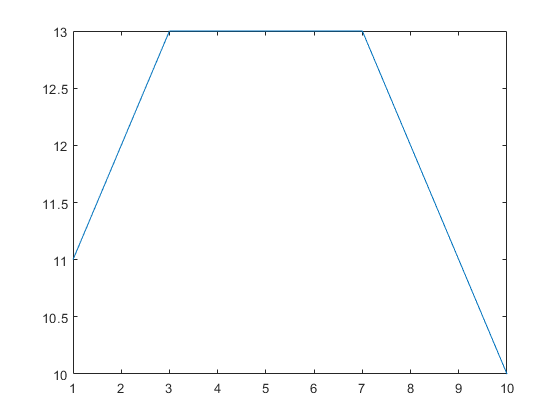

% Preamble
fig_basic = figure(); hold off;
% Geometries
plot(tab_record.olin)

**Exercise:** Add a line to plot the Wellesley results; describe what happens. Do you get both curves to show with this code?

% Solution
% Preamble
fig_ex = figure(); hold off;
% Geometries
plot(tab_record.olin)

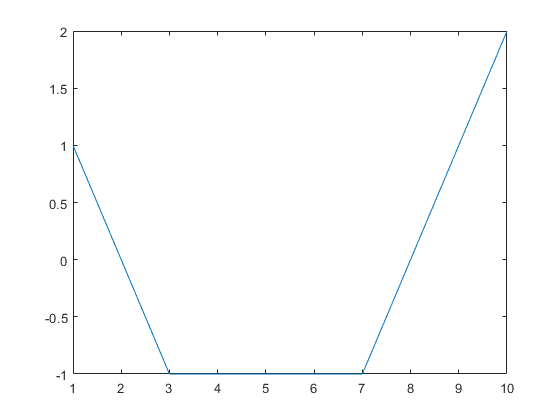

plot(tab_record.wellesley)

By default Matlab sets `hold off`; we can show multiple curves at once by setting `hold on`:

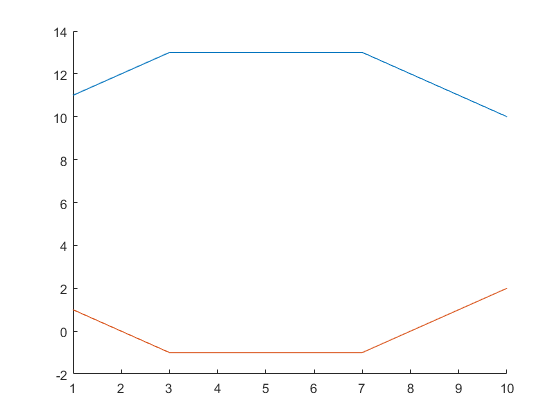

% Preamble
fig_bad = figure(); hold on;
% Geometries
plot(tab_record.olin)
plot(tab_record.wellesley)

However, there is a *fatal flaw* with this plot; it doesn't have any axis labels! **Don't forget the axis labels.** A plot is totally unintelligible without them!

The following code generates an acceptable figure; it has axis labels and a color legend to distinguish between the curves.

% Preamble
fig_acceptable = figure(); hold on;
% Geometries
plot(tab_record.olin); label1 = "Olin";
plot(tab_record.wellesley); label2 = "Wellesley";
% Tail
xlabel("Time (minutes)")
ylabel("Bikes")
legend({label1, label2})

Often we'll want to *save* a figure to keep a convenient record of results, or to include in a presentation/report. We can use the function `saveas`() to save a *specified* figure.

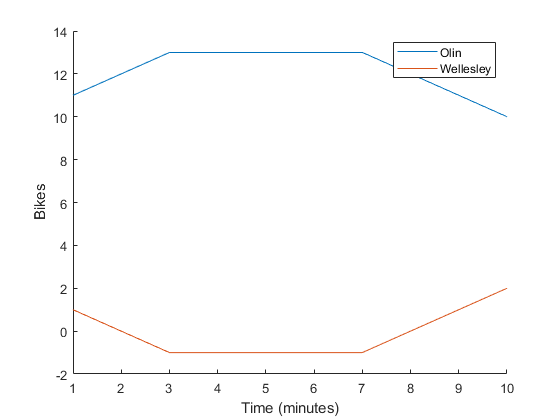

% Uncomment to save the figure to a .png file
saveas(fig_acceptable, "bikeshare.png")

Note that we have to pass the *figure handle* `f` in order to specify which figure we want to save. This is (partly) why we call `figure().`

**Last Exercise:** Wrap the simulation code from this section in a function named `fcn_simulate` that takes four inputs: `tab_state, p_o2w`, `p_w2o`, and `num_steps`.

To get started, first create a *new file* called `fcn_simulate.m`.

It should:

- Create a table to hold the results.

- Use a for loop to run `step` the number of times specified by `num_steps`, passing along the specified values of `p_o2w` and `p_w2o`.

- After each step, it should save the state of the simulation in the record table.

- At the end, the function should return the simulation record.

To test your function:

- Create a table with the initial state of the system.

- Call `fcn_simulate` with appropriate parameters.

- Create a plot of the results.

- Save the resulting figure.

To get you started, here is the desired function signature and documentation. Your job is to write the code that *implements *this function idea.

% function tab_record = fcn_simulate(tab_state, p_o2w, p_w2o, num_steps)
% simulate_bikeshare Run a bikeshare simulation
%
% Usage
%   state = fcn_simulate(state, p_o2w, p_w2o, num_steps)
%
% Arguments
%   state = bikeshare state
%   p_o2w = probability of bicycle going from Olin to Wellesley
%   p_w2o = probability of bicycle going from Wellesley to Olin
%   num_steps = number of steps to simulate
%
% Examples
%   % Create an initial state
%   tab_state = fcn_make_table("olin", 10, "wellesley", 3);
%   % Simulate 60 steps with p_o2w = 0.3, p_w2o = 0.2
%   tab_record = fcn_simulate(tab_state, 0.3, 0.2, 60);
%
% TODO: Write the function!
%
% end

Solution

%% TODO